[K_miu, ~, gamma] = dksyn(entiress, 1, 1);

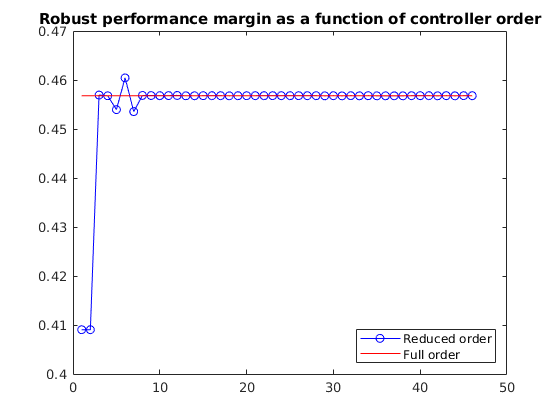

NS = size(K_miu.A, 1);
% NS = order(K_robust); 
StateOrders = 1:NS;
Kred = reduce(K_miu,StateOrders);
% Compute robust performance margin for each reduced controller
CLP = lft(entiress,Kred);
for k=1:NS
   PM(k) = robgain(CLP(:,:,k),gamma);
end

% Compare robust performance of reduced- and full-order controllers
PMfull = PM(end).LowerBound;
plot(StateOrders,[PM.LowerBound],'b-o',...
   StateOrders,repmat(PMfull,[1 NS]),'r');
title('Robust performance margin as a function of controller order')
legend('Reduced order','Full order','location','SouthEast')

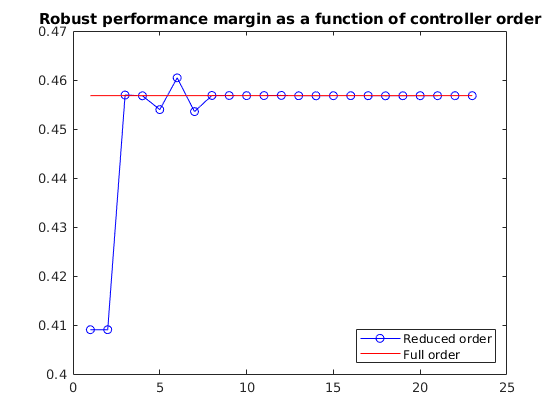

PMfull = PM(end).LowerBound;
plot(1:length(PM),[PM.LowerBound],'b-o',...
   1:length(PM),repmat(PMfull,[1 length(PM)]),'r');
title('Robust performance margin as a function of controller order')
legend('Reduced order','Full order','location','SouthEast')

Kmiu = c2d(reduce(K_miu, 6), Ts);
% Kmiu = c2d(K_miu, Ts);
[KmiuA, KmiuB, KmiuC, KmiuD] = ssdata(Kmiu);
[KA, KB, KC, KD] = ssdata(Kmiu);
save ./matlab_omega_control/H_miu_control_matrix.mat KA KB KC KD
save all_current_space_2.mat